EEG signals of 4 part of the head such as P4,Cz,F8 and T7.  Dataset has 20 subjects and 8(1,2,5,6,7,8,9,10) different experiments where experiment 1,2 has three sessions for each subject. 

In the matlab live script, we will observe the frequency response corresponding with the different experiment for each subject.

% Suppress the warning about modified column headers
warning('off', 'MATLAB:table:ModifiedAndSavedVarnames');

list of dataset from our model.

datasetlist();

Frequency_s01_Central.xlsx
Frequency_s01_Frontal.xlsx
Frequency_s01_Periferal.xlsx
Frequency_s01_Temporal.xlsx
Frequency_s02_Central.xlsx
Frequency_s02_Frontal.xlsx
Frequency_s02_Periferal.xlsx
Frequency_s02_Temporal.xlsx
Frequency_s03_Central.xlsx
Frequency_s03_Frontal.xlsx
Frequency_s03_Periferal.xlsx
Frequency_s03_Temporal.xlsx
Frequency_s04_Central.xlsx
Frequency_s04_Frontal.xlsx
Frequency_s04_Periferal.xlsx
Frequency_s04_Temporal.xlsx
Frequency_s05_Central.xlsx
Frequency_s05_Frontal.xlsx
Frequency_s05_Periferal.xlsx
Frequency_s05_Temporal.xlsx
Frequency_s06_Central.xlsx
Frequency_s06_Frontal.xlsx
Frequency_s06_Periferal.xlsx
Frequency_s06_Temporal.xlsx
Frequency_s07_Central.xlsx
Frequency_s07_Frontal.xlsx
Frequency_s07_Periferal.xlsx
Frequency_s07_Temporal.xlsx
Frequency_s08_Central.xlsx
Frequency_s08_Frontal.xlsx
Frequency_s08_Periferal.xlsx
Frequency_s08_Temporal.xlsx
Frequency_s09_Central.xlsx
Frequency_s09_Frontal.xlsx
Frequency_s09_Periferal.xlsx
Frequency_s09_Temporal.xlsx
F

List of figures...

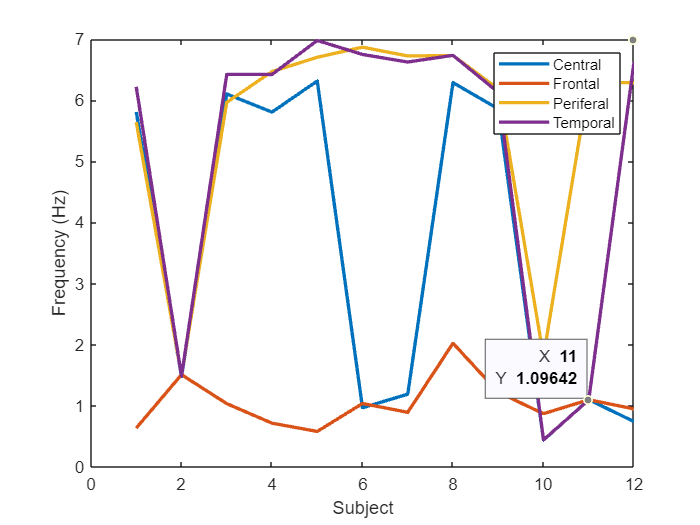

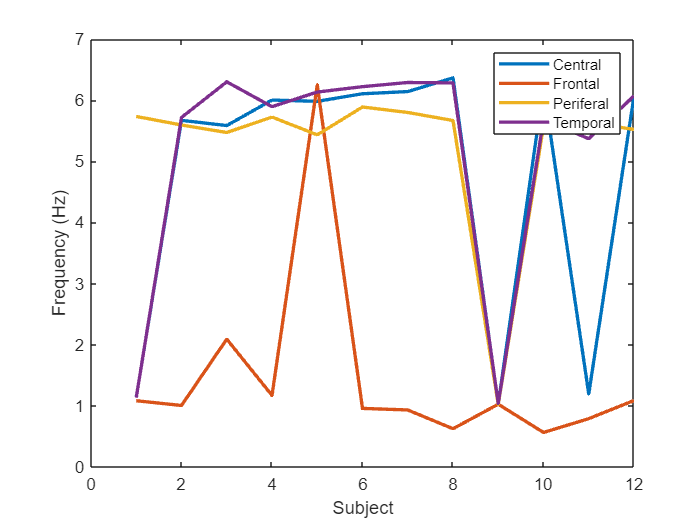

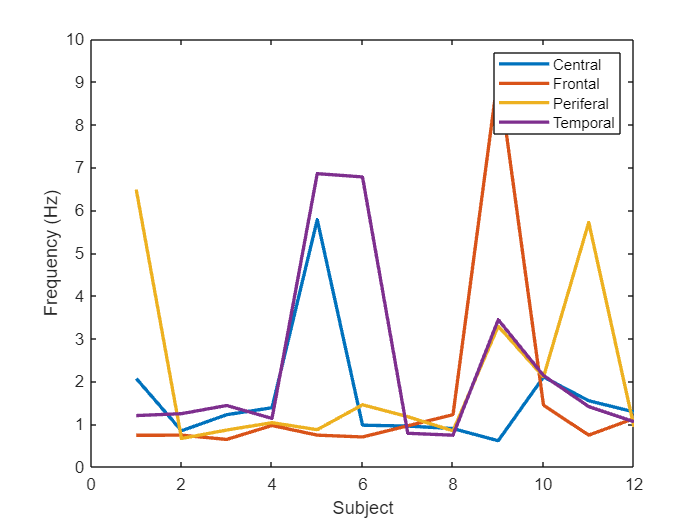

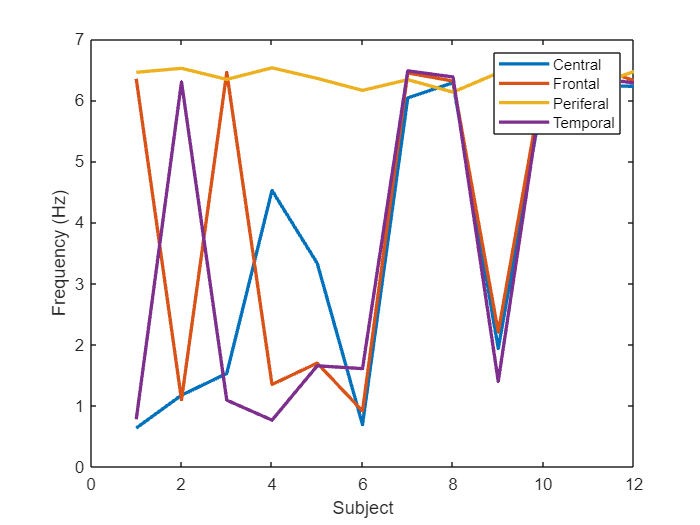

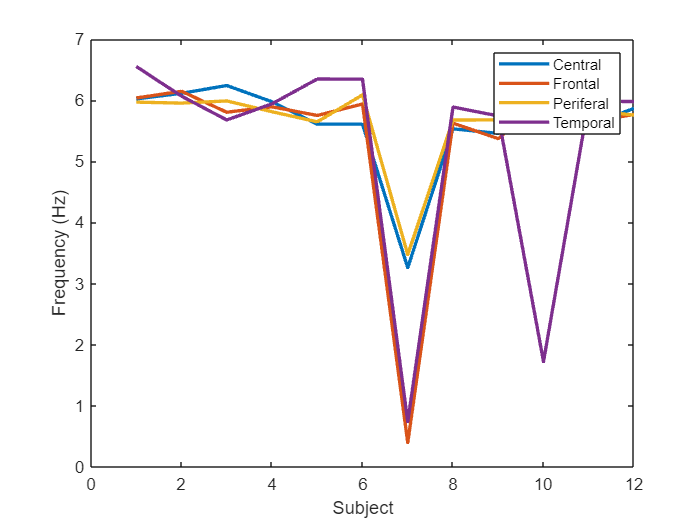

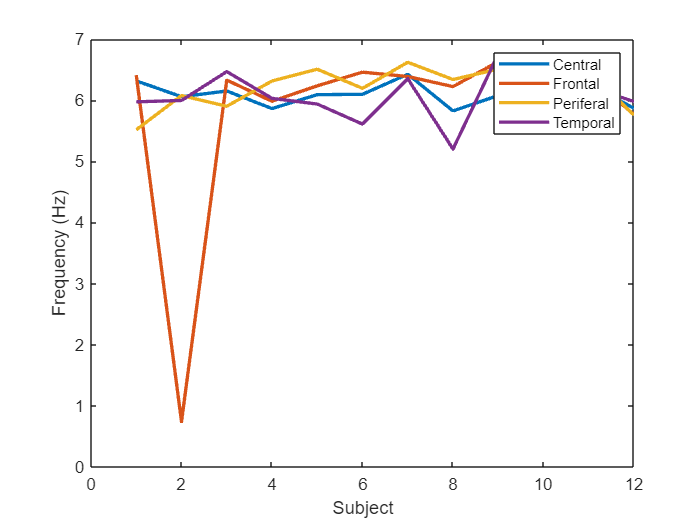

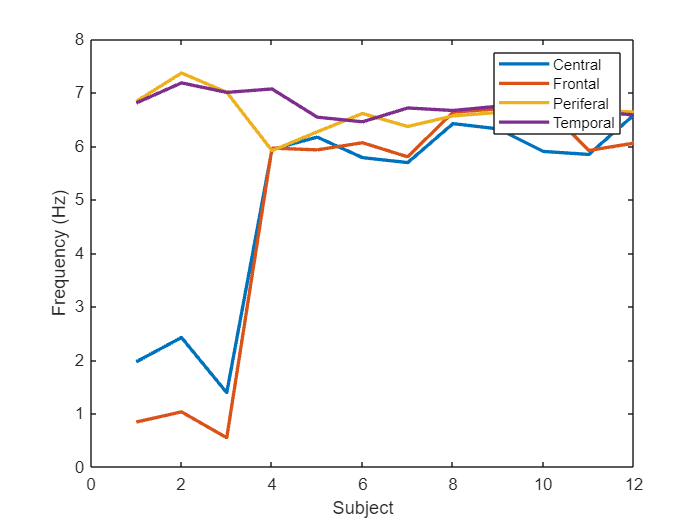

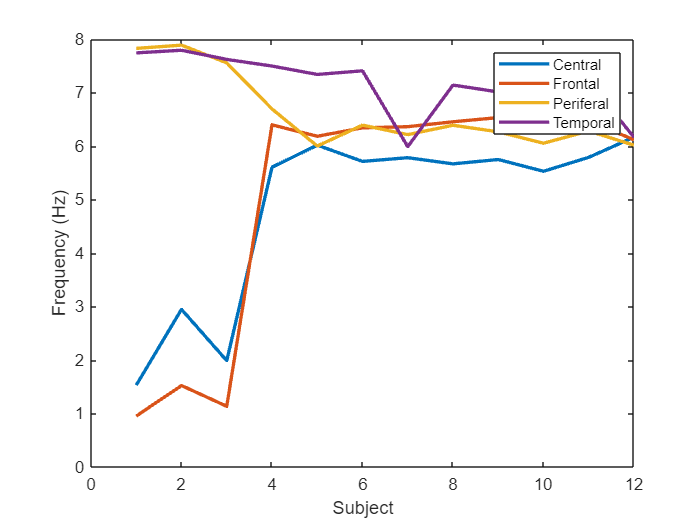

drawfigure();

Function ...

function datasetlist()
    directoryPath = 'K:\Father Fourier Analysis Report\';
    
    for i = 1:20
        % Use the dir function to get information about files
        if i>=10
            pattern = strcat('s',num2str(i));
        else
            pattern = strcat('s0',num2str(i));
        end
        filesInfo = dir(fullfile(directoryPath, ['Frequency_' pattern '*.xlsx']));
        for j = 1:numel(filesInfo)
            disp(filesInfo(j).name);
        end
    end
end

function drawfigure()
    directoryPath = 'K:\Father Fourier Analysis Report\';
    for i = 1:20
        if i>=10
            pattern = strcat('s',num2str(i));
        else
            pattern = strcat('s0',num2str(i));
        end
        filesInfo = dir(fullfile(directoryPath, ['Frequency_' pattern '*.xlsx']));
    
        figure(i);
        for j = 1:numel(filesInfo)
            dataTable = readtable(fullfile(directoryPath,filesInfo(j).name));
            dataTableX = dataTable.DominantFrequency;
            x_axis = 1:length(dataTableX);
            plot(x_axis,dataTableX,'LineWidth', 2);
            hold on
        end
        hold off
        xlabel('Subject');
        ylabel('Frequency (Hz)');
        legend('Central', 'Frontal', 'Periferal', 'Temporal');
    end
end